% clear all;
% close all;
% clc;

% gurobi_setup;
% initCobraToolbox(false);
% setenv('GUROBI_PATH', 'C:\gurobi1001\win64\matlab');
% changeCobraSolver('gurobi', 'all');

# PLOTS

This code makes sure to plot the core genes and core reactions inclussion, as well as to provide a better undersanding of the GPR rules

% load the data
metabolic_genes = load("metabolic_genes.mat");
metabolic_genes = metabolic_genes.metabolic_genes;
metabolic_genes_P = load("metabolic_genes_P.mat");
metabolic_genes_P = metabolic_genes_P.metabolic_genes_P;

currentFolder = pwd;
cd('C:/Users/PC/OneDrive/Documentos/Systems_Biology_master/Internship/Internship/Data');
model = load('SysBio_COBRA_v1.17_consensus.mat'); % Human1 metabolic model
model = model.myModel;
%[fluxConsistentMetBool, fluxConsistentRxnBool, fluxInConsistentMetBool, fluxInConsistentRxnBool, ~, fluxConsistModel] = findFluxConsistentSubset(model);
%model_p = fluxConsistModel; % load the new model with no blocked reactions
%save('model_p.mat', 'model_p');
model_p = load('model.mat');
model_p = model_p.model;
cd(currentFolder)

## Start the ploting


% % Pruned and unpruned data
%IMR90_Y2 = table2array(metabolic_genes(:, 8));
IMR90_Y2 = table2array(mean(metabolic_genes(:, 8), 2))

IMR90_Y2 =     2.0923
    2.2535
    1.3807
    0.5487
    1.7719
    0.0457
    0.0734
    0.1856
    0.0866
    0.3394


%IMR90_Y2_P = table2array(metabolic_genes_P(:, 8));
IMR90_Y2_P = table2array(mean(metabolic_genes_P(:, 8), 2))

IMR90_Y2_P =     2.0923
    2.2535
    1.3807
    0.5487
    1.7719
    0.0457
    0.0734
    0.0866
    0.3394
    1.7364



% Core genes and core reactions
%IMR90_Y2_coreGenes = results_CoreGenes(8, 'CoreGeneIDs');
%test = IMR90_Y2_coreGenes{1, 1};
IMR90_Y2_length = length(IMR90_Y2_P);

% for core Reactions
%IMR90_Y2_coreReact = CoreReact_Sample(1, 8)
IMR90_Y2_RLength = length(model_p.rxns);%IMR90_Y2_coreReact{1, 1})

% Initialises vectors for storing recall values
HK_CG_G = zeros(1, 100);
HK_CR_R = zeros(1, 100);
HK_CG_G_recall_values = zeros(1, 100);
HK_CR_R_recall_values = zeros(1, 100);

% Loop to iterate over each percentile
for p = 1:100
    percentile_value = prctile(IMR90_Y2, p);

    % Normalises data based on the current percentile
    IMR90_Y2_norm = IMR90_Y2_P ./ percentile_value;

    % Calculate the recall for core genes
    IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm >= 1);
    HK_CG_G(p) = (length(IMR90_Y2_CG)/IMR90_Y2_length)*100;
    HK_CG_G_rec = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
    HK_CG_G_recall = (length(HK_CG_G_rec) / length(hkg_met)) * 100;
    HK_CG_G_recall_values(p) = HK_CG_G_recall;

    % Prepare the expression data
    expressionData.gene = gene_names_P;
    expressionData.value = IMR90_Y2_norm;

    % Map gene expression to reactions
    IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionData, 'false'); % Maybe here with the pruned one?
    IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);

    % Calculate the recall for core reactions
    HK_CR_R(p) = (length(IMR90_Y2_CR)/IMR90_Y2_RLength)*100;
    HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
    HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
    HK_CR_R_recall_values(p) = HK_CR_R_recall;
end

## Save the results and load them

save('HK_CG_G_1.mat', 'HK_CG_G');
save('HK_CG_G_recall_values_1.mat', 'HK_CG_G_recall_values');
save('IMR90_Y2_norm_1.mat', 'IMR90_Y2_norm');
save('IMR90_Y2_normCR_1.mat', 'IMR90_Y2_normCR');
save('HK_CR_R_1.mat', 'HK_CR_R');
save('HK_CR_R_recall_values_1.mat', 'HK_CR_R_recall_values');
% Load the data
HK_CG_G = load('HK_CG_G_1.mat');
HK_CG_G = HK_CG_G.HK_CG_G;
HK_CG_G_recall_values = load('HK_CG_G_recall_values_1.mat');
HK_CG_G_recall_values = HK_CG_G_recall_values.HK_CG_G_recall_values;
IMR90_Y2_norm = load('IMR90_Y2_norm_1.mat');
IMR90_Y2_norm = IMR90_Y2_norm.IMR90_Y2_norm;
IMR90_Y2_normCR = load('IMR90_Y2_normCR_1.mat');
IMR90_Y2_normCR = IMR90_Y2_normCR.IMR90_Y2_normCR;
HK_CR_R = load('HK_CR_R_1.mat');
HK_CR_R = HK_CR_R.HK_CR_R;
HK_CR_R_recall_values = load('HK_CR_R_recall_values_1.mat');
HK_CR_R_recall_values = HK_CR_R_recall_values.HK_CR_R_recall_values;

## Plot the results

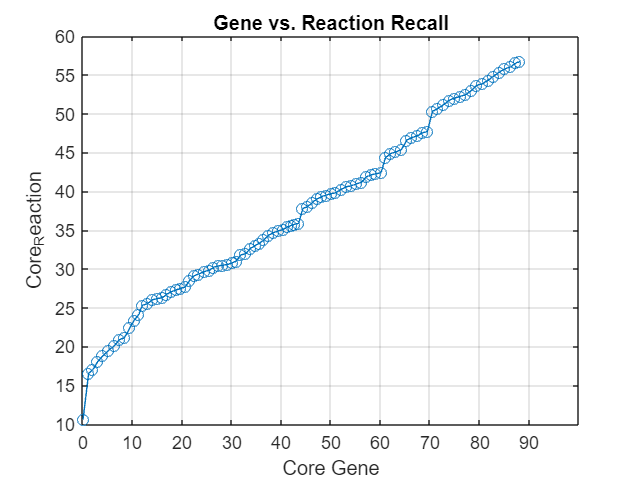

% CORE GENE INCLUSSION VS CORE REACTION INCLUSION
plot(HK_CG_G, HK_CR_R, 'o-');
xlabel('Core Gene');
ylabel('Core_Reaction');
title('Gene vs. Reaction Recall');
grid on;
xticks(0:10:90);
% Save the plot
saveas(gcf, 'Gene_vs_Reaction_1.png');

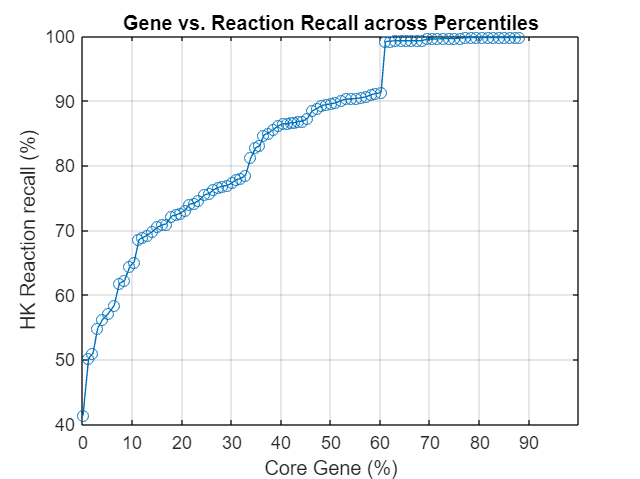


% CORE GENE INCLUSION VS HOUSEKEEPING REACTIONS RECALL
plot(HK_CG_G, HK_CR_R_recall_values, 'o-');
xlabel('Core Gene (%)');
ylabel('HK Reaction recall (%)');
title('Gene vs. Reaction Recall across Percentiles');
grid on;
xticks(0:10:90);
% Save the plot
saveas(gcf, 'Gene_vs_HKReaction_1.png');

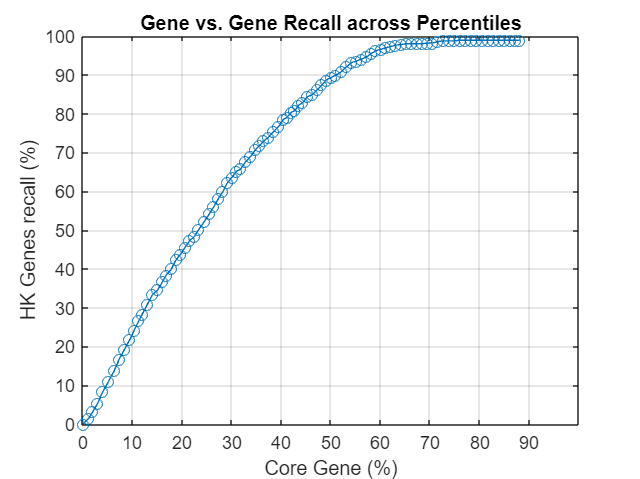


% CORE GENE INCLUSION VS HOUSEKEEPING GENES RECALL
plot(HK_CG_G, HK_CG_G_recall_values, 'o-');
xlabel('Core Gene (%)');
ylabel('HK Genes recall (%)');
title('Gene vs. Gene Recall across Percentiles');
grid on;
xticks(0:10:90);
% Save the plot
saveas(gcf, 'Gene_vs_HKGene_1.png');

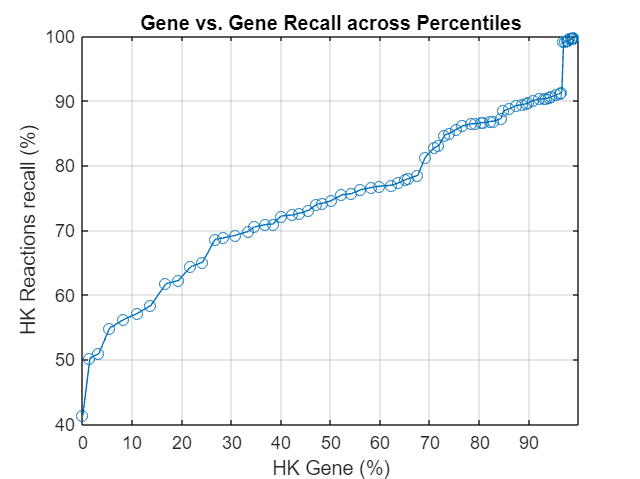


% HOUSEKEEPING GENE RECALL VS HOUSEKEEPING REACTIONS RECALL
plot(HK_CG_G_recall_values, HK_CR_R_recall_values, 'o-');
xlabel('HK Gene (%)');
ylabel('HK Reactions recall (%)');
title('Gene vs. Gene Recall across Percentiles');
grid on;
xticks(0:10:max(HK_CG_G_recall_values));

% Save the plot
saveas(gcf, 'HKGene_vs_HKReactions_1.png');

# TEST WHAT MARIAN SUGGESTED ABOUT PERCENTAGE OF ORs

% Pruned and unpruned data
%IMR90_Y2 = table2array(metabolic_genes(:, 8));
IMR90_Y2 = table2array(mean(metabolic_genes(:, 8), 2))
%IMR90_Y2_P = table2array(metabolic_genes_P(:, 8));
IMR90_Y2_P = table2array(mean(metabolic_genes_P(:, 8), 2))

% Core genes and core reactions
%IMR90_Y2_coreGenes = results_CoreGenes(8, 'CoreGeneIDs');
%test = IMR90_Y2_coreGenes{1, 1};
IMR90_Y2_length = length(IMR90_Y2_P);

% for core Reactions
%IMR90_Y2_coreReact = CoreReact_Sample(1, 8)
IMR90_Y2_RLength = length(model_p.rxns);%IMR90_Y2_coreReact{1, 1})

% Initialises vectors for storing recall values
HK_CG_G_T = zeros(1, 40);
HK_CR_R_T = zeros(1, 40);
HK_CG_G_recall_values_T = zeros(1, 40);
HK_CR_R_recall_values_T = zeros(1, 40);
HK_CG_G_T_Names = {};
HK_CR_R_T_Names = {};

% Loop to iterate over each percentile
for p = 100:-1:60
    percentile_value = prctile(IMR90_Y2, p);

    % Normalises data based on the current percentile
    IMR90_Y2_norm = IMR90_Y2_P ./ percentile_value;

    % Calculate the recall for core genes
    IMR90_Y2_CG = gene_names_P(IMR90_Y2_norm >= 1);
    HK_CG_G_T_Names{p} = IMR90_Y2_CG;
    HK_CG_G_T(p) = (length(IMR90_Y2_CG)/IMR90_Y2_length)*100;
    HK_CG_G_rec_T = hkg_met(ismember(hkg_met, IMR90_Y2_CG));
    HK_CG_G_recall_T = (length(HK_CG_G_rec_T) / length(hkg_met)) * 100;
    HK_CG_G_recall_values_T(p) = HK_CG_G_recall_T;

    % Prepare the expression data
    expressionData.gene = gene_names_P;
    expressionData.value = IMR90_Y2_norm;

    % Map gene expression to reactions
    IMR90_Y2_normCR = mapExpressionToReactions(model_p, expressionData, 'false'); % Maybe here with the pruned one?
    IMR90_Y2_CR = model_p.rxns(IMR90_Y2_normCR >= 1);

    % Calculate the recall for core reactions
    HK_CR_R_T_Names{p} = IMR90_Y2_CR;
    HK_CR_R_T(p) = (length(IMR90_Y2_CR)/IMR90_Y2_RLength)*100;
    HK_CR_R_rec = housekeep_react_unique(ismember(housekeep_react_unique, IMR90_Y2_CR));
    HK_CR_R_recall = (length(HK_CR_R_rec) / length(housekeep_react_unique)) * 100;
    HK_CR_R_recall_values_T(p) = HK_CR_R_recall;
end

save('HK_CG_G_T_Names_1.mat', 'HK_CG_G_T_Names');
save('HK_CR_R_T_Names_1.mat', 'HK_CR_R_T_Names');

% load the data
HK_CG_G_T_Names = load('HK_CG_G_T_Names_1.mat');
HK_CG_G_T_Names = HK_CG_G_T_Names.HK_CG_G_T_Names;
HK_CR_R_T_Names = load('HK_CR_R_T_Names_1.mat');
HK_CR_R_T_Names = HK_CR_R_T_Names.HK_CR_R_T_Names;


## Check the or and AND rules

Go throught the 60 percentile one by one, to explore the reactions that are included, and based on that, analyze the percentage of those that are coded by 'or' rules.

%% another test 
met_ens = metabolic_genes_P.Properties.RowNames;
GPR_rules = model_p.grRules;

geneRulesCount = analyzeGPRRules(met_ens, GPR_rules);

results_test = analyzeCoreElements(IMR90_Y2, IMR90_Y2_P, met_ens, model);

% Percentages test
percentages = calculatePercentages(geneRulesCount);
disp(percentages);

    single: 12.6110
       and: 8.3010
        or: 75.5625
    and_or: 3.5256



## Print the results

% Prepare the variables to store the results
percentiles = 100:-1:60;
percentOrRules = zeros(length(percentiles), 1);
percentAndRules = zeros(length(percentiles), 1);
percentSingleRules = zeros(length(percentiles), 1);
percentCombinedRules = zeros(length(percentiles), 1);

% Obtain the data from each structure inside results_tests
for i = 1:length(percentiles)
    percentileKey = sprintf('P%d', percentiles(i));
    percentOrRules(i) = results_test.(percentileKey).percentOrRules;
    percentAndRules(i) = results_test.(percentileKey).percentAndRules;
    percentSingleRules(i) = results_test.(percentileKey).percentSingleRules;
    percentCombinedRules(i) = results_test.(percentileKey).percentCombinedRules;
end

% Create a table witht the extracted data
resultsTable = table(percentiles', percentOrRules, percentAndRules, percentSingleRules, percentCombinedRules, ...
    'VariableNames', {'Percentile', 'PercentORRules', 'PercentANDRules', 'PercentSingleRules', 'PercentCombinedRules'});

% Show the table
disp(resultsTable);

    Percentile    PercentORRules    PercentANDRules    PercentSingleRules    PercentCombinedRules
    __________    ______________    _______________    __________________    ____________________

       100                 0                  0                   0                      0       
        99            98.039                  0              1.9608                      0       
        98            96.996                  0              2.1459                0.85837       
        97            93.684                  0              5.5263                0.78947       
        96            91.827                  0              7.4519                0.72115       
        95            88.841                  0              10.515                0.64378       
        94            83.056                 